Create database!

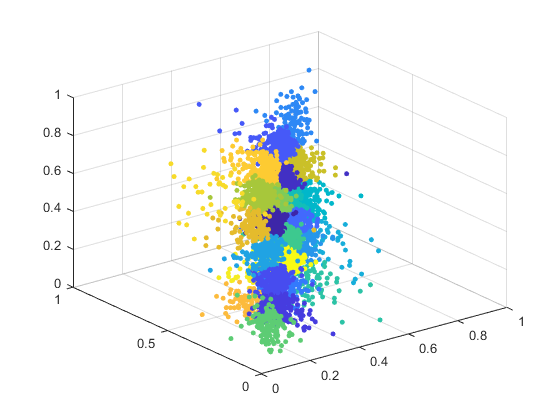

Error using disp
Too many input arguments.

Error in filtering (line 73)
disp(strcat(strcat('Database has been created containing:', int2str(size(smallDatabase,2)))),' images');

numberOfCluster = 25;
clusterSize = 8; 
tinyImgSize = 24; 

% The resulting number of images comes from numberOfCluster * cluterSize
% 25 * 4 = 100 images for example

[smallDatabase, meanSmallDB] = filtering(numberOfCluster,clusterSize,tinyImgSize);

Create reconstructed image from smaller images that comes from the database

% Name of the file (Must be of type jpg)
fileName = 'grill.jpg';
% The size for each "cell" that goes through the image. Recommended size = 8
cellSize = 8;
% Number of 'good-matches' to use SSIM on. Higher = better quality (but also more compute heavy)
n = 3;

% call function to create image
[imgOUT, imgSSIM, imgSNR, imgDE] = image_rec_v1(fileName, smallDatabase, meanSmallDB, cellSize, n);

% show the final image
imshow(lab2rgb(imgOUT))